% Plant
A_hor = [-1/t_V,  0, 0, 0;
          cm(1)/I_yz_lookup(1), 0, 0, 0;
          0,    1, 0, 0;
          0,    1/m(1), -g, 0];

b_hor = [1/t_V; 0; 0; 0];

Angle controller

% Requirments
zeta = 1;
ts2 = 1;
wn = 4/(zeta*ts2)

wn = 4

Ts_hor = 1/(500);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =     -4
    -4



p_z_want = exp(p_s_want*Ts_hor)

p_z_want =     0.9920
    0.9920



% Plant
c_ang = [0, 0, 1, 0];
d_ang = 0;
sysC = ss(A_hor,b_hor,c_ang,d_ang);
poles = pole(sysC)

poles =      0
     0
   -10
     0


zeros = zero(sysC)

zeros = 0

sysD_ang = c2d(sysC,Ts_hor,'zoh');

% Controller

[C_ang,info] = pidtune(sysD_ang,'PID')

C_ang =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 59.6, Ki = 3.85, Kd = 123, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 4.3899
           PhaseMargin: 60.0000


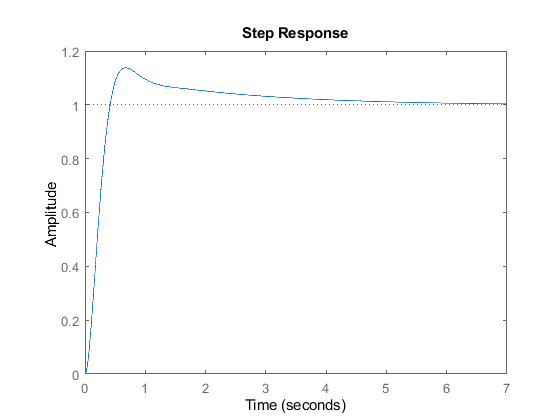

step(feedback(C_ang*sysD_ang,1))